ICO5: Polynomial Fits 

Data from Before:

% -- ORIGINAL DATA: --------------------------
warning off; 
x1 = [46, 49, 51, 52, 54, 56, 57, 58, 59, 60];
y1 = [40, 50, 55, 63, 72, 70, 77, 73, 90, 93];
x2 = [61, 62, 63,  64,  66,  67,  68,  71,  72];
y2 = [96, 88, 99, 110, 113, 120, 127, 137, 132];
x = [x1, x2];
xx = min(x):1:max(x);
y = [y1, y2];
%deg = (length(x1)-1);
poly_rsq = zeros(1,3);
lin_rsq = zeros(1,1);

Modifications:

% -- DATA SHIFT: --------------------------
X = x;
XX = min(X):1:max(X);
Y = y ./ (x.^2);
% -- ORIG. LIN.FIT ------------------------
f1 = polyfit(x,y,1);
f2 = polyfit(x,y,2);
f3 = polyfit(x,y,3);
yy1 = polyval(f1, xx);
yy2 = polyval(f2, xx);
yy3 = polyval(f3, xx);

% -- NEW   LIN.FIT ------------------------
g = polyfit(X, Y, 1);
YY = polyval(g, XX).*(xx.^2);

New R^2 Values:

%-- COMPUTE R^2 VALUES: ----------------------
poly_rsq(1) = myRsq(y, yy1);
poly_rsq(2) = myRsq(y, yy2);
poly_rsq(3) = myRsq(y, yy3);
lin_rsq(1) = myRsq(Y, polyval(g, XX));

Plot Results:

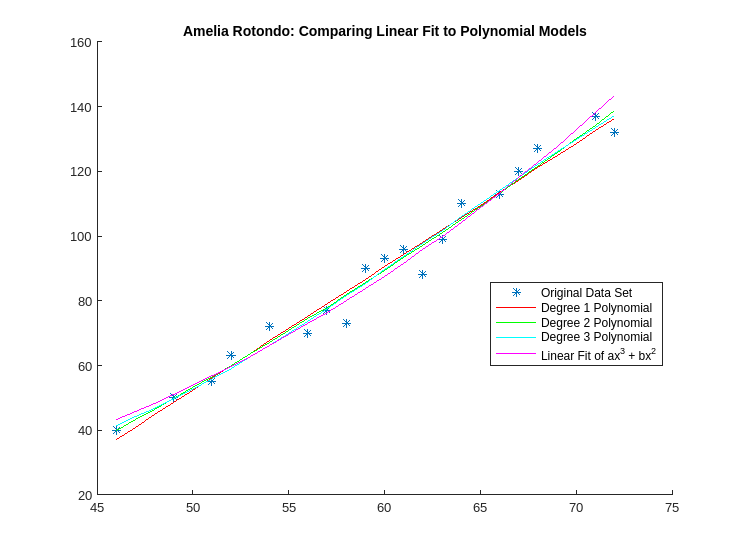

figure(1); clf; hold on;
plot(x, y, '*', 'DisplayName', 'Original Data Set');
plot(xx, yy1, 'r', 'DisplayName', sprintf('Degree 1 Polynomial'));
plot(xx, yy2, 'g', 'DisplayName', sprintf('Degree 2 Polynomial'));
plot(xx, yy3, 'c', 'DisplayName', sprintf('Degree 3 Polynomial'));
plot(XX, YY, 'm', 'DisplayName', 'Linear Fit of ax^3 + bx^2');
legend('Location', 'best');
title('Amelia Rotondo: Comparing Linear Fit to Polynomial Models')

fprintf('\n\n------------------------------------\n');



------------------------------------


fprintf('R^2 for Polynomial of Degrees 1 Through 3:\n %f %f %f\n',poly_rsq);

R^2 for Polynomial of Degrees 1 Through 3:
 0.482062 0.460955 0.456222


fprintf('R^2 for Linear Fit of ax^3 + bx^2:\n %f', lin_rsq);

R^2 for Linear Fit of ax^3 + bx^2:
 0.338029